# Feedforward neural network architecture search

Data Preparation

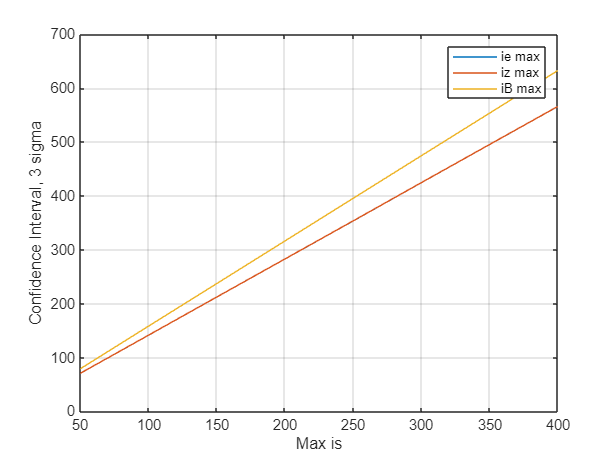

beta =    -0.0284
    1.4144


ie_max = 353.5621

ie_max = 353.3280

beta =    -0.0558
    1.4146


iz_max = 353.5896

iz_max = 353.4193

beta =     0.0552
    1.5807


iB_max = 395.2333

iB_max = 395.2787

Von_max = 6000

vc_ref = 18000

E = 8.9100e+05

VB = 12000

IB = 400

IE = 375

Nbuffer_variables = 32

Nsamples = 100000

Ninputs = 27

Noutputs = 5

ans =           27      100000


ans =            5      100000


Ninputs = 27

Nsamples = 100000

Noutputs = 5

Nsamples = 100000

Nsamples = 99726

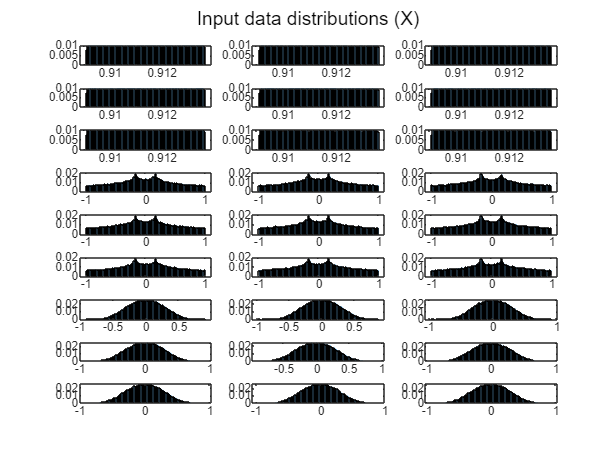

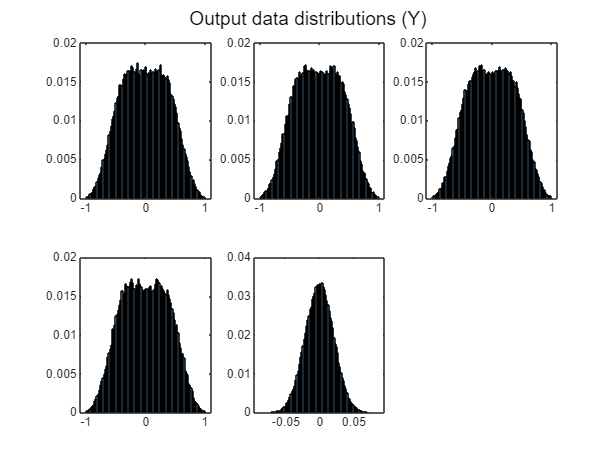

run("Simulations\DataPreparation.mlx")

PERFORM SEARCH (CAREFUL)

perform_search = false;

Architecture search

% % Create folders to save results
% mkdir('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Architectures');
% mkdir('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Performance');


% Define architecture range (width and depth)
env = classM3C()

env =   classM3C with properties:

                    Tf: 0.5000
                    Ts: 2.0000e-05
                    Ti: 1.0000e-04
                Ti_idx: 5
                    Tl: 1.0000e-04
                Tl_idx: 5
                    Ax: 7000
                   fxi: 50
                   wx0: 314.1593
                    Ay: 5000
                   fyi: 30
                   wy0: 188.4956
                     A: [6×9 double]
                 pinvA: [9×6 double]
                     m: 9
                     N: [9×4 double]
                 pinvN: [4×9 double]
                     C: 0.0200
                     L: 0.0200
                     R: 1.0000e-03
               Tabc_ab: [2×3 double]
               Tab_abc: [3×2 double]
      Tabc_dq_function: @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]
               Vxy_max: 12000
               Von_max: 6000
                Is

Ninputs = env.getObservationInfo.Dimension(1)

Ninputs = 27

Noutputs = env.getActionInfo.Dimension(1)

Noutputs = 5


Nlayers_range = 1:3

Nlayers_range =      1     2     3


Nneurons_range = round(linspace(round(Ninputs/2), 3*Ninputs, 5))

Nneurons_range =     14    31    48    64    81



if perform_search
tic

% Initialize matrices for results
results = [];

% Iterate over architecture range
for Nlayers = Nlayers_range
    for Nneurons = Nneurons_range
        try
            net_name = [num2str(Nlayers) 'L' num2str(Nneurons) 'N'];

            NNgenerator_args = struct();
            NNgenerator_args.Ninputs = Ninputs;
            NNgenerator_args.Noutputs = Noutputs;
            NNgenerator_args.NFFlayers = Nlayers;
            NNgenerator_args.NRlayers = 0;
            NNgenerator_args.NFFneurons = Nneurons;
            NNgenerator_args.Nwindow = 1;
            NNgenerator_args.hidden_activation = 'reluLayer';
            NNgenerator_args.output_activation = 'tanhLayer';
            NNgenerator_args.dropout = 0;
            NNgenerator_args.WinitFcn = 'narrow-normal';
            NNgenerator_args.BinitFcn = 'narrow-normal';
            NNgenerator_args.train_bias = false;
            NNgenerator_args.scale_data = false;
            NNgenerator_args.Xmax = Xmax;
            NNgenerator_args.Ymax = Ymax;
            
            FFnet = NNgenerator(NNgenerator_args);
            FFnet = dlupdate(@double, FFnet);

            % Training
            NNtrain_args = struct();
            NNtrain_args.net = FFnet;
            NNtrain_args.X_train = dlX_tr;
            NNtrain_args.Y_train = dlY_tr;
            NNtrain_args.X_val = dlX_val;
            NNtrain_args.Y_val = dlY_val;
            NNtrain_args.regularization = 0;
            NNtrain_args.lr_i = 1e-2;
            NNtrain_args.lr_f = 1e-6;
            NNtrain_args.plots = 'none';
            
            FFnet = NNtrain(NNtrain_args);

            % Evaluating
            trainPerformance = mse(FFnet.predict(dlX_tr), dlY_tr);
            valPerformance = mse(FFnet.predict(dlX_val), dlY_val);

            % Results
            results(end+1, :) = [Nlayers, Nneurons, trainPerformance, valPerformance];

            % Save net
            save(fullfile('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Architectures', ['A' net_name '.mat']), 'FFnet');

        catch ME
            disp(['Error ' net_name ': ' ME.message]);
            continue;
        end
    end
end
csvwrite('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Performance/performance.csv', results);

toc
end

Elapsed time is 26142.046549 seconds.


# Results analysis

## Heatmap

data = readmatrix('NeuralNetwork/Imitation/ArchitectureSearch/FFNN/Results/Performance/performance.csv');
data(:, 5) = data(:, 3)./data(:, 4); % Generalization (MSE_tr/MSE_val)
data(:, 3:5) = data(:, 3:5)*100; % Percentage-like
Narchitectures = size(data, 1)

Narchitectures = 15

Nlayers_range = sort(unique(data(:, 1)))'

Nlayers_range =      1     2     3


Nneurons_range = sort(unique(data(:, 2)))'

Nneurons_range =     14    31    48    64    81


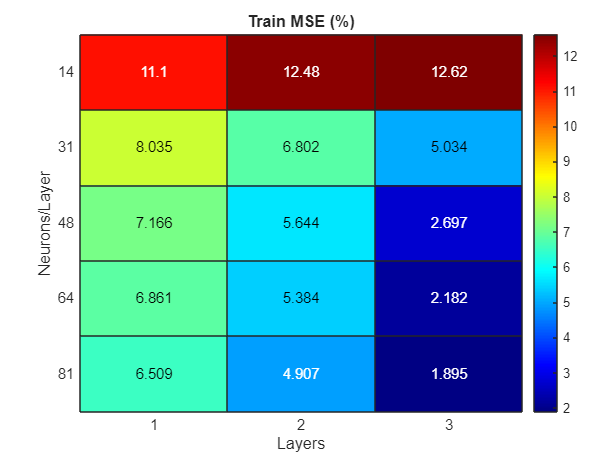


% Performances
trainPerformance = reshape(data(:, 3), [length(Nneurons_range), length(Nlayers_range)]);
valPerformance = reshape(data(:, 4), [length(Nneurons_range), length(Nlayers_range)]);
generalizationPerformance = reshape(data(:, 5), [length(Nneurons_range), length(Nlayers_range)]);

% Training
figure;
heatmap(Nlayers_range, Nneurons_range, round(trainPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Train MSE (%)');
colorbar;
colormap jet;

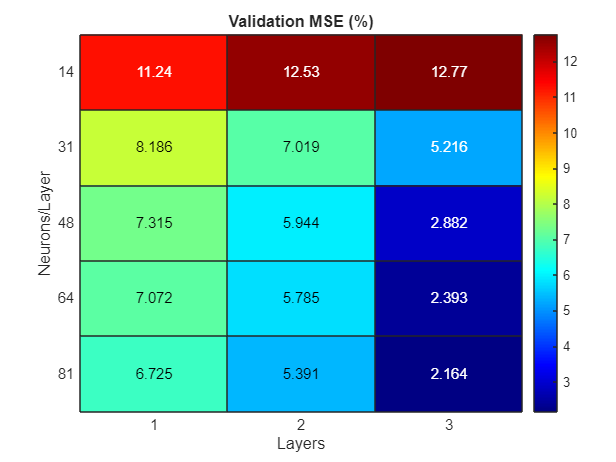


% Validation
figure;
heatmap(Nlayers_range, Nneurons_range, round(valPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Validation MSE (%)');
colorbar;
colormap jet;

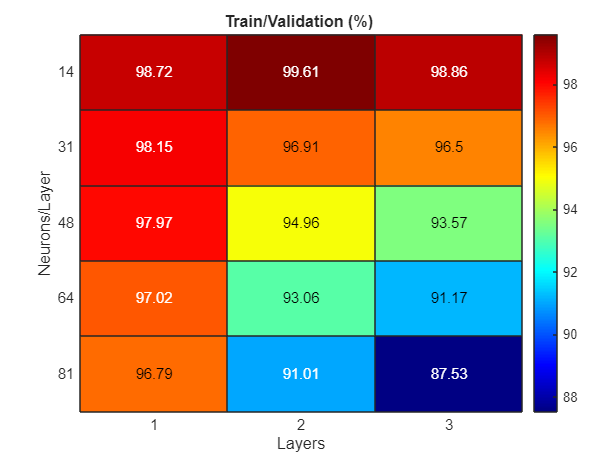


% Generalization
figure;
heatmap(Nlayers_range, Nneurons_range, round(generalizationPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Train/Validation (%) ');
colorbar;
colormap jet;

## 3d Plot

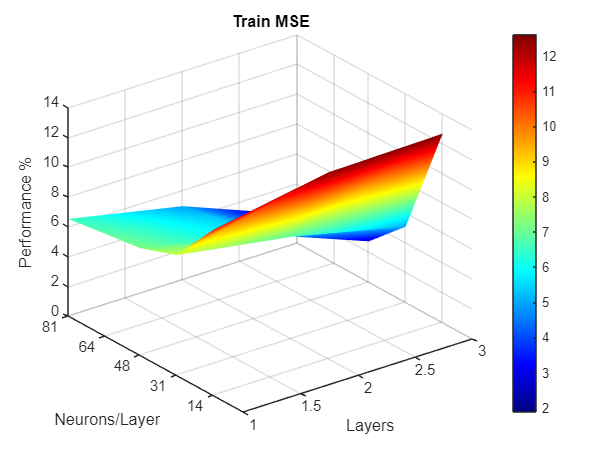

% Training
figure;
surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance %');
title('Train MSE');
colorbar;
colormap jet;
shading interp;

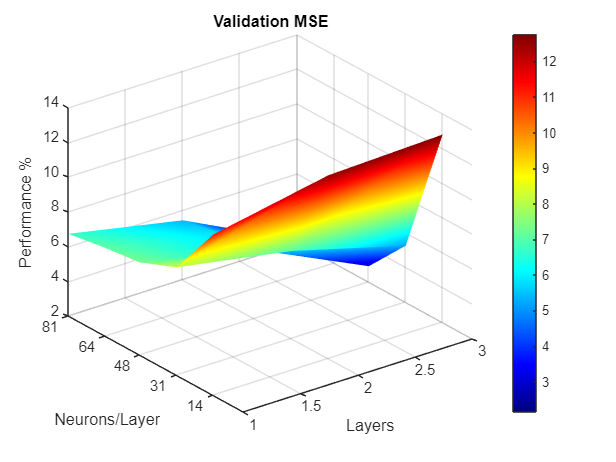


% Validation
figure;
surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance %');
title('Validation MSE');
colorbar;
colormap jet;
shading interp;

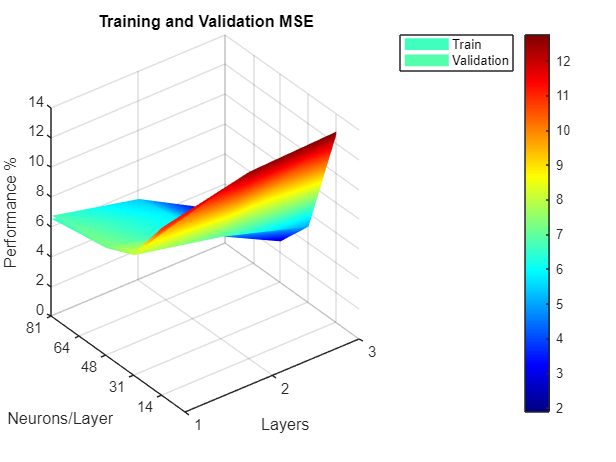


% Training and validation
figure;
surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
hold on
surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
hold off
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance %');
title('Training and Validation MSE');
legend(["Train", "Validation"])
colorbar;
colormap jet;
shading interp;

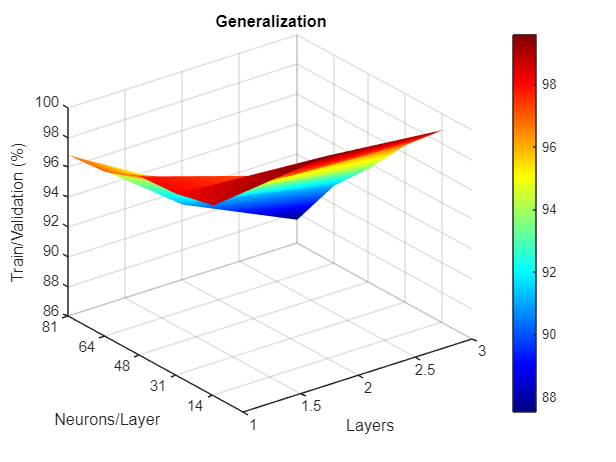


% Generalization
figure;
surf(Nlayers_range, Nneurons_range, generalizationPerformance, 'EdgeColor', 'none');
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Train/Validation (%)');
title("Generalization");
colorbar;
colormap jet;
shading interp;

## Tables

From saved performances

Nbest_architectures = 10;

train_table = sortrows(data, 3);
validation_table = sortrows(data, 4);
diff_table = sortrows(data, 5, 'descend');

train_table = train_table(1:Nbest_architectures, :);
validation_table = validation_table(1:Nbest_architectures, :);
diff_table = diff_table(1:Nbest_architectures, :);

train_table = array2table(train_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Gen'});
validation_table = array2table(validation_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr',  'MSE_val', 'Gen'});
diff_table = array2table(diff_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Gen'});

disp([num2str(Nbest_architectures) ' best training performances']);

10 best training performances


disp(train_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Gen  
    ______    _____________    ______    _______    ______
      3            81          1.8946    2.1644     87.535
      3            64          2.1815    2.3927     91.173
      3            48          2.6968    2.8821     93.571
      2            81          4.9068    5.3914     91.012
      3            31          5.0338    5.2162     96.503
      2            64          5.3841    5.7854     93.064
      2            48           5.644    5.9436     94.959
      1            81          6.5094    6.7254     96.788
      2            31          6.8021    7.0187     96.914
      1            64          6.8608    7.0717     97.018



disp([num2str(Nbest_architectures) ' best validation performances']);

10 best validation performances


disp(validation_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Gen  
    ______    _____________    ______    _______    ______
      3            81          1.8946    2.1644     87.535
      3            64          2.1815    2.3927     91.173
      3            48          2.6968    2.8821     93.571
      3            31          5.0338    5.2162     96.503
      2            81          4.9068    5.3914     91.012
      2            64          5.3841    5.7854     93.064
      2            48           5.644    5.9436     94.959
      1            81          6.5094    6.7254     96.788
      2            31          6.8021    7.0187     96.914
      1            64          6.8608    7.0717     97.018



disp([num2str(Nbest_architectures) ' best generalization performances']);

10 best generalization performances


disp(diff_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Gen  
    ______    _____________    ______    _______    ______
      2            14          12.476    12.525     99.609
      3            14           12.62    12.765     98.864
      1            14          11.096     11.24     98.719
      1            31          8.0348    8.1863     98.149
      1            48          7.1664    7.3147     97.973
      1            64          6.8608    7.0717     97.018
      2            31          6.8021    7.0187     96.914
      1            81          6.5094    6.7254     96.788
      3            31          5.0338    5.2162     96.503
      2            48           5.644    5.9436     94.959
